try
% Start the Data Collector Set
system('logman start CPU_Log');

clear; close all; clc;

## Plot settings

cMap=[0.6*ones(256,2), linspace(1, 0, 256)'];
fontSize=15;
markerSize=20;

## Control parameters

Creating control parameters depending on the type of demo the user wants to run 

#### Generating Geometry

gradType= 'levelSet'; % choose between cellSize or levelSet

%%% Change lattice density!!!
levelset= 1; %Isosurface level, corresponding to volume fraction

inputStruct.L=[3 1 1]; % characteristic length
inputStruct.Ns=100; % number of sampling points, resolution
inputStruct.surfaceCase='g'; %Surface type
inputStruct.numPeriods=[9 3 3]; %Number of periods in each direction [6 2 2]
% inputStruct.numPeriods=[6 2 2]; %Number of periods in each direction [6 2 2]
inputStruct.gradType=gradType;

% from 2.7
inputStruct.GF=[2, 2]; % Gradient factors

**Abaqus Simulation**

% Path names
defaultFolder = fileparts(fileparts(mfilename('fullpath')));
savePath=fullfile(defaultFolder,'assets','temp');

% !!! These folders used to not exist
[status, msg, msgID] = mkdir(savePath);
if ~status
    warning('Failed to create directory: %s', msg);
end

% Defining file names
abaqusInpFileNamePart='Lattice_FEA';
abaqusInpFileName=fullfile(savePath,[abaqusInpFileNamePart,'.inp']); %INP file name
abaqusDATFileName=fullfile(savePath,[abaqusInpFileNamePart,'.dat']); %DAT file nameme for exporting stress

% Define applied displacement & direction
displacementMagnitude = -0.2; %

% Material parameter set
E_youngs=5000;
v_poisson=0.33;

% Set parameters for individual gyroid
% NOTE: Not all geometry parameters yield a valid mesh. If the image resolution 
% is poor, or if the point spacing is too large, the mesh may be invalid. 

radiusInner = 0.3; 
radiusOuter = 1.2; 
height = 2; 
Dim=[radiusInner, radiusOuter, 2*pi, height]; % size vector
Ns=150; % number of sampling points
numPeriods=[2 12 2]; %Number of periods in each direction
levelset=0.5 ; %Isosurface level

pointSpacing=(radiusOuter-radiusInner)/40;

tolDir=pointSpacing/5; %Tolerance for detecting sides after remeshing

## Create triply periodic minimal surface

[S,X,Y,Z] = gradTPMS(inputStruct);

% Isosurface
[F,V] = isosurface(X,Y,Z,S,levelset);

%Capping ends
[fc,vc]=isocaps(X,Y,Z,S,levelset, 'above'); 

% Join, merge, and clean unused
[f,v,c] = FV_arrange(F,V,fc,vc);

## Visualize surface

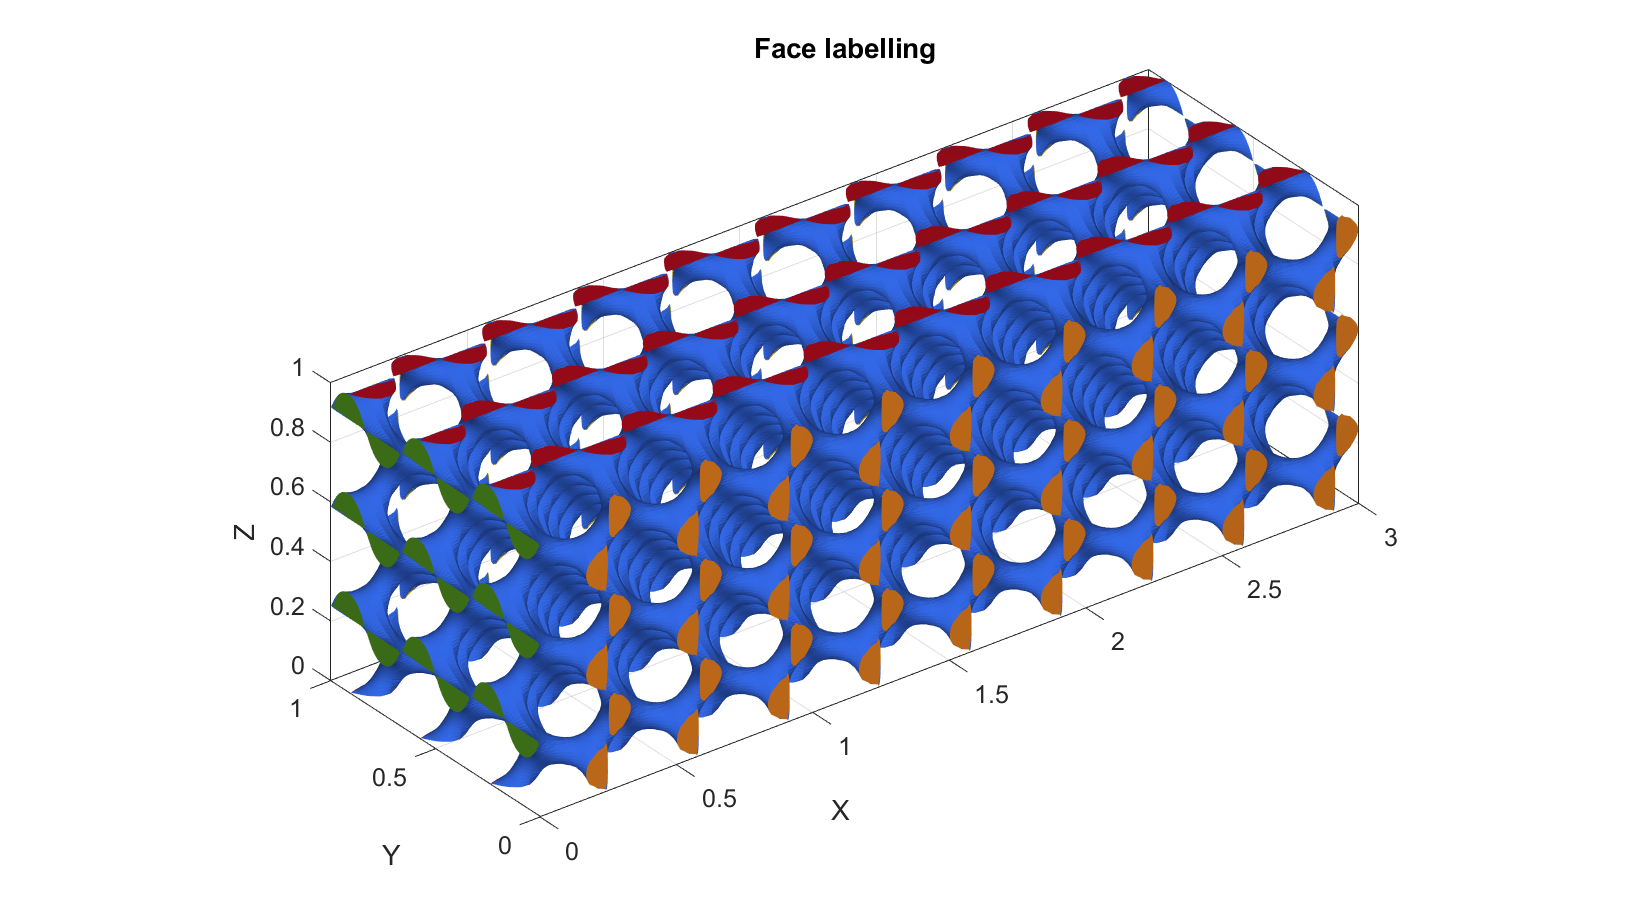

cFigure;
title('Face labelling');
hp1 = gpatch(f,v,c,'none', 1); 
hp1.FaceColor = 'Flat';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

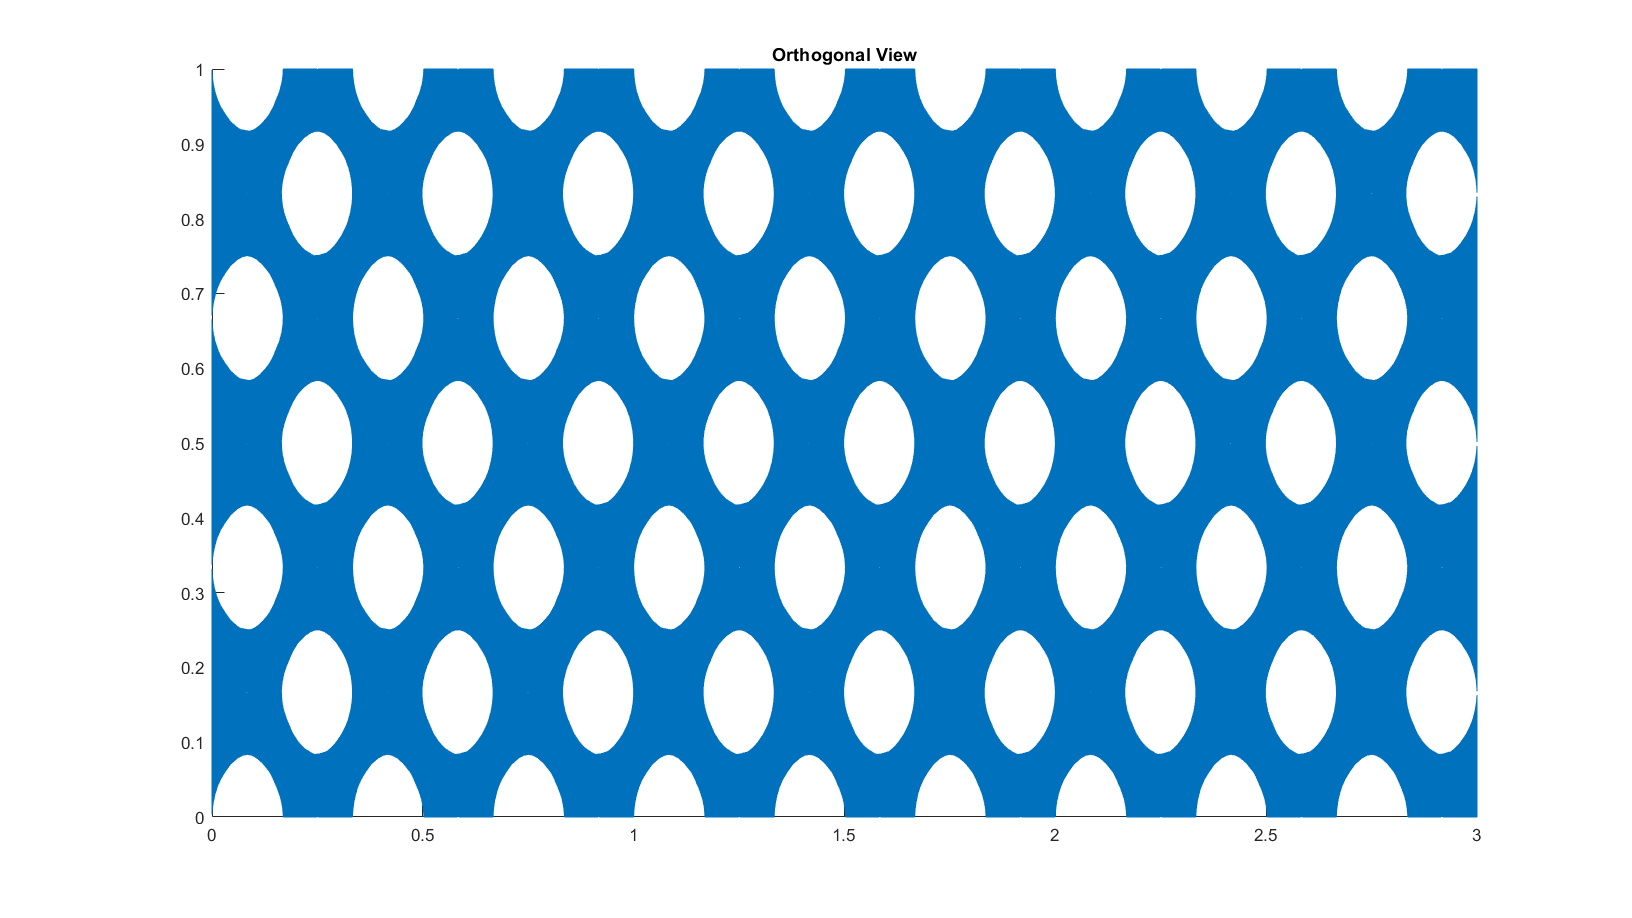


cFigure;        
title('Orthogonal View');
% Create the patch with uniform color
hp2 = gpatch(f, v, 'none', 1);
hp2.FaceColor = [0 0.4470 0.7410];
hp2.EdgeColor = [0 0.4470 0.7410];

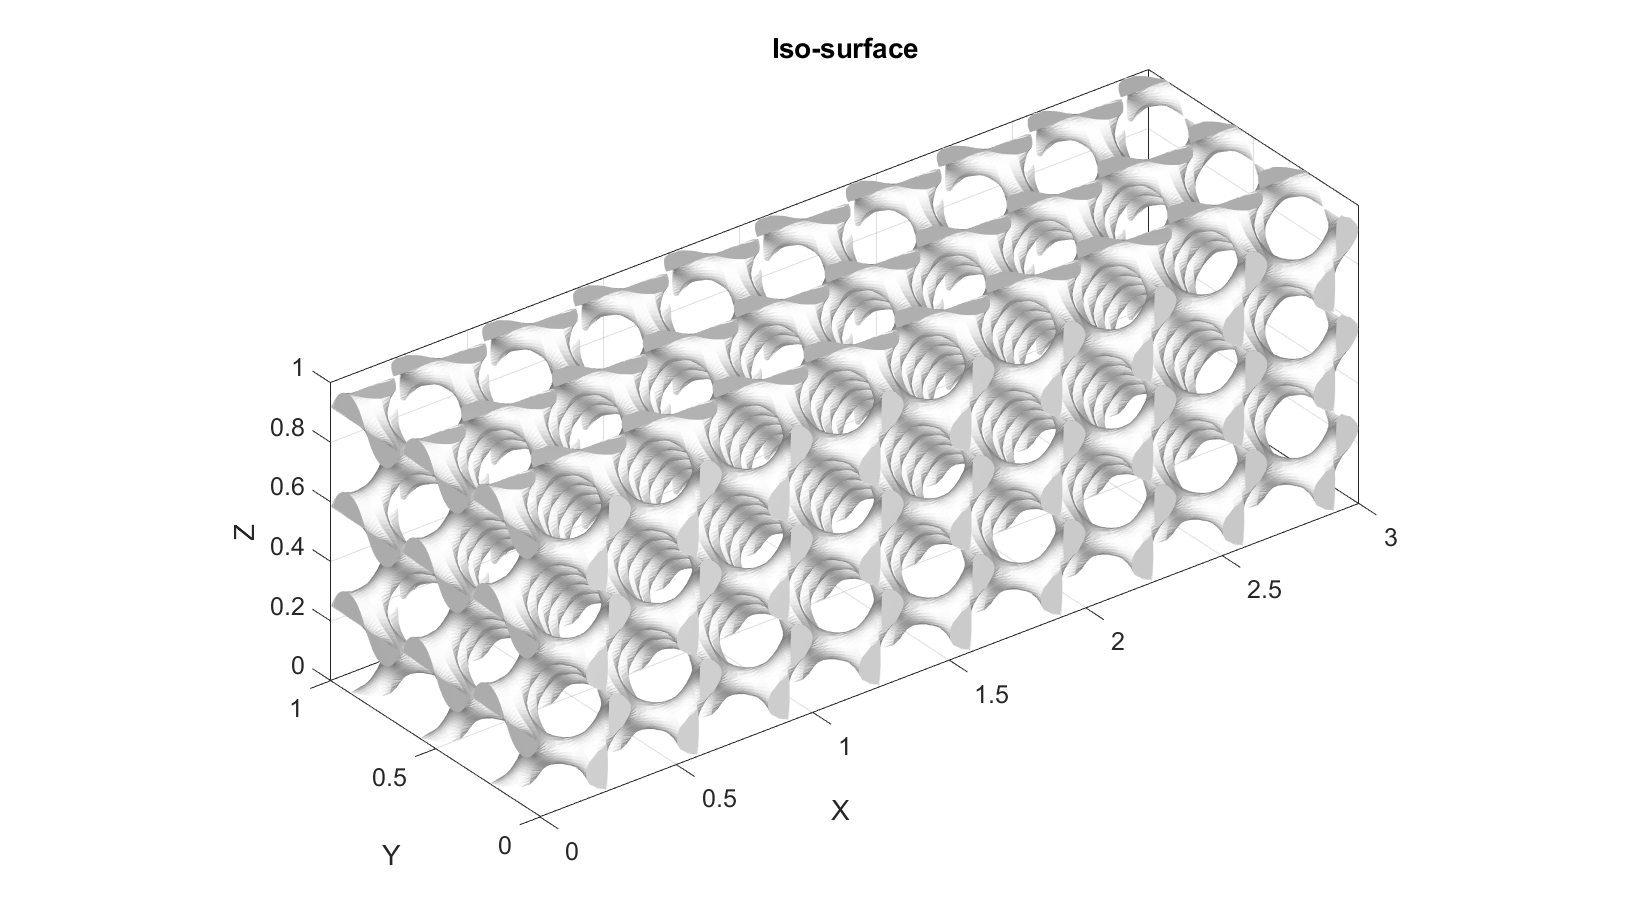


cFigure;
title('Iso-surface');
hp3 = gpatch(f,v,c,'none', 1); 
hp3.FaceColor = 'w';
% hp3.EdgeColor = 'k';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;


% hp2 = gpatch(f,v,v(:,1),'none', 1); % color gradient along X-direction
% hp2.FaceColor = 'interp'; % Use interpolated shading
% colormap(gca,cMap) ; %Set Colormap
% cbh = colorbar;  %Create Colorbar
% cbh.Ticks = linspace(0, 3, 4); %Create 4 ticks 10%-40%
% cbh.TickLabelInterpreter = 'tex';
% cbh.TickLabels = {'10%','20%','30%','40%'} ; %Replace the labels
% of these 8 ticks with the numbers

## Remesh using geomgram

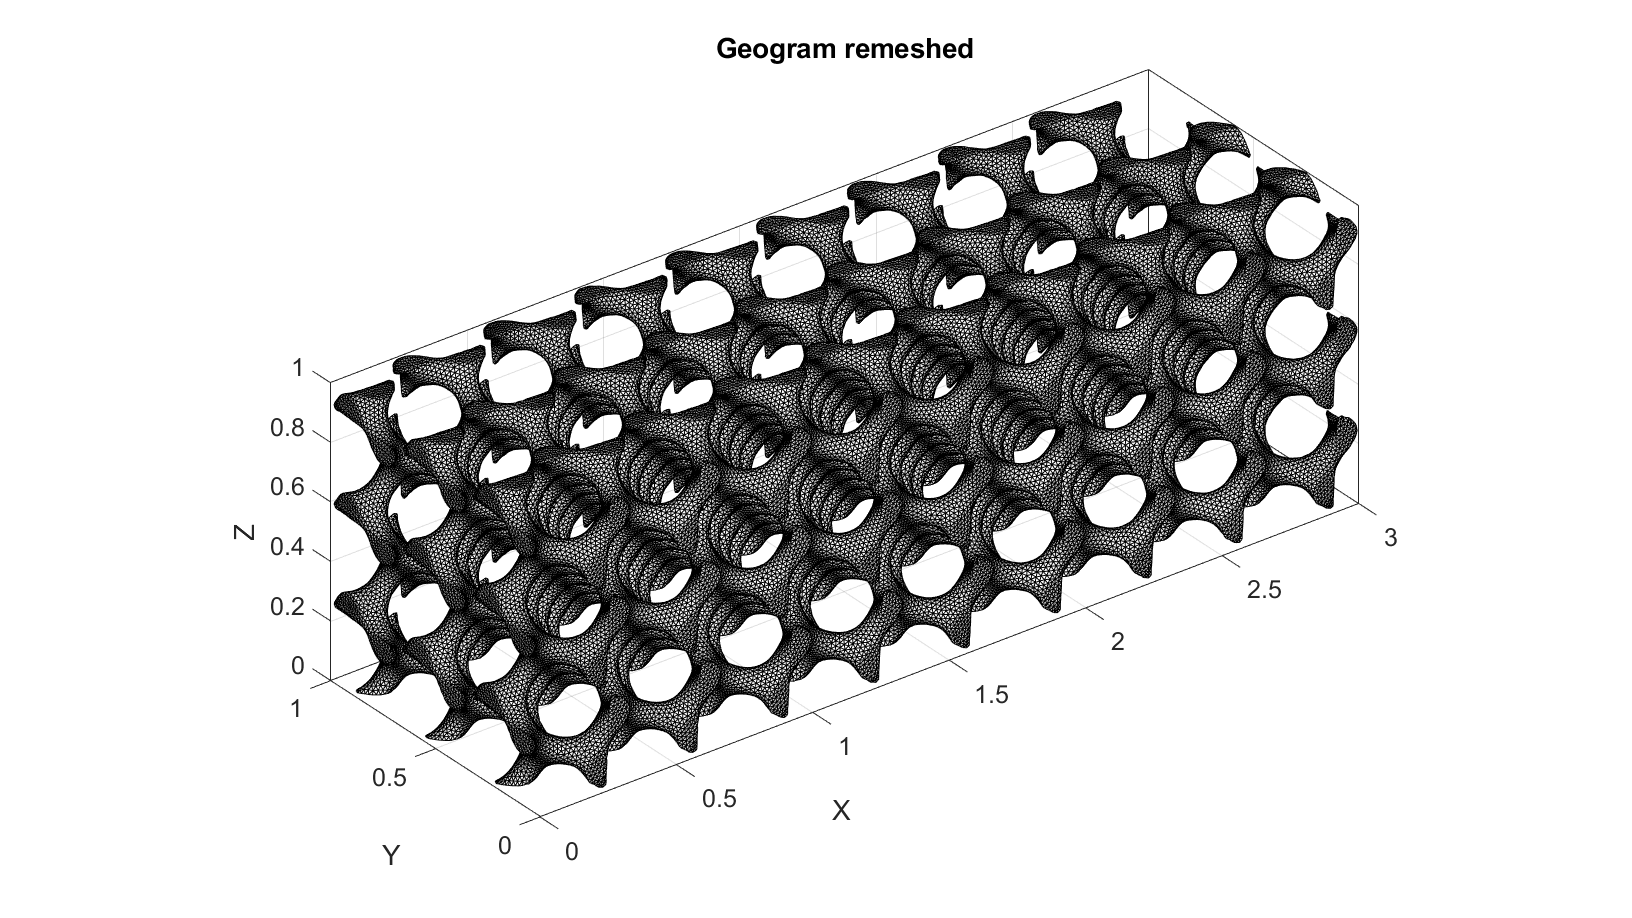

pointSpacing=0.015; % changing this to see if meshes within 250k
optionStruct.pointSpacing=pointSpacing;
[F,V]=ggremesh(f,v,optionStruct);
C=zeros(size(F,1),1);

% Visualizing geometry
cFigure; hold on;
title('Geogram remeshed','FontSize',fontSize);
gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;

drawnow;

## Tetrahedral meshing using tetgen (see also `runTetGen`)

Create tetgen input structure

inputStruct.stringOpt='-pq1.2AaY';
inputStruct.Faces=F;
inputStruct.Nodes=V;
inputStruct.holePoints=[];
inputStruct.faceBoundaryMarker=C; %Face boundary markers
inputStruct.regionPoints=getInnerPoint(F,V); %region points
inputStruct.regionA=2*tetVolMeanEst(F,V);
inputStruct.minRegionMarker=2; %Minimum region marker

% Mesh model using tetrahedral elements using tetGen
[meshOutput]=runTetGen(inputStruct); %Run tetGen

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:44:30
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:44:30
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:44:31
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:44:31
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.701 
Creating surface mesh ... 
Surface mesh seconds:  0.15 
Recovering boundaries... 
Boundary recovery seconds:  0.963 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.399 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.181 
Refining mesh... 
Refinement seconds:  3.528 
Optimizing mesh... 
Optimization seconds:  0.406 
 
Writing C:\Users\rusc


fprintf("%i Elements generated",size(meshOutput.elements,1));

1137654 Elements generated


%%%%%%%%%%%%%%%% while loop start
maxIterations = 20;
iterationCount = 0;

while iterationCount < maxIterations

    [F,V]=ggremesh(f,v,optionStruct);
    C=zeros(size(F,1),1);

    inputStruct.stringOpt='-pq1.2AaY';
    inputStruct.Faces=F;
    inputStruct.Nodes=V;
    inputStruct.holePoints=[];
    inputStruct.faceBoundaryMarker=C; %Face boundary markers
    inputStruct.regionPoints=getInnerPoint(F,V); %region points
    inputStruct.regionA=2*tetVolMeanEst(F,V);
    inputStruct.minRegionMarker=2; %Minimum region marker

    [meshOutput]=runTetGen(inputStruct); %Run tetGen

    numElements = size(meshOutput.elements, 1);

    fprintf("%i Elements generated",size(meshOutput.elements,1));

    if numElements > 250000
        optionStruct.pointSpacing = optionStruct.pointSpacing + 0.001
    elseif numElements < 200000 % reduce pointSpacing
        optionStruct.pointSpacing = optionStruct.pointSpacing - 0.001
    else
        break;
    end

    iterationCount = iterationCount + 1;
end

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:45:03
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:45:03
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:45:04
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:45:04
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.606 
Creating surface mesh ... 
Surface mesh seconds:  0.127 
Recovering boundaries... 
Boundary recovery seconds:  0.857 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.379 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.179 
Refining mesh... 
Refinement seconds:  3.249 
Optimizing mesh... 
Optimization seconds:  0.39 
 
Writing C:\Users\rusc

1137496 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0160


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:45:31
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:45:31
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:45:32
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:45:32
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.536 
Creating surface mesh ... 
Surface mesh seconds:  0.116 
Recovering boundaries... 
Boundary recovery seconds:  0.736 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.33 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.18 
Refining mesh... 
Refinement seconds:  2.95 
Optimizing mesh... 
Optimization seconds:  0.313 
 
Writing C:\Users\rusco\

938192 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0170


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:45:55
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:45:55
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:45:55
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:45:55
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.47 
Creating surface mesh ... 
Surface mesh seconds:  0.125 
Recovering boundaries... 
Boundary recovery seconds:  0.709 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.301 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.148 
Refining mesh... 
Refinement seconds:  2.281 
Optimizing mesh... 
Optimization seconds:  0.271 
 
Writing C:\Users\rusc

779978 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0180


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:46:16
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:46:16
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:46:17
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:46:17
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.437 
Creating surface mesh ... 
Surface mesh seconds:  0.088 
Recovering boundaries... 
Boundary recovery seconds:  0.554 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.254 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.12 
Refining mesh... 
Refinement seconds:  1.781 
Optimizing mesh... 
Optimization seconds:  0.227 
 
Writing C:\Users\rusc

654825 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0190


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:46:34
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:46:34
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:46:35
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:46:35
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.399 
Creating surface mesh ... 
Surface mesh seconds:  0.083 
Recovering boundaries... 
Boundary recovery seconds:  0.519 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.237 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.109 
Refining mesh... 
Refinement seconds:  1.511 
Optimizing mesh... 
Optimization seconds:  0.185 
 
Writing C:\Users\rus

557518 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0200


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:46:52
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:46:52
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:46:53
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:46:53
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.373 
Creating surface mesh ... 
Surface mesh seconds:  0.076 
Recovering boundaries... 
Boundary recovery seconds:  0.549 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.221 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.1 
Refining mesh... 
Refinement seconds:  1.392 
Optimizing mesh... 
Optimization seconds:  0.158 
 
Writing C:\Users\rusco

480019 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0210


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:47:07
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:47:07
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:47:08
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:47:08
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.404 
Creating surface mesh ... 
Surface mesh seconds:  0.084 
Recovering boundaries... 
Boundary recovery seconds:  0.457 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.206 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.094 
Refining mesh... 
Refinement seconds:  1.166 
Optimizing mesh... 
Optimization seconds:  0.139 
 
Writing C:\Users\rus

414276 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0220


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:47:21
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:47:21
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:47:22
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:47:22
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.399 
Creating surface mesh ... 
Surface mesh seconds:  0.113 
Recovering boundaries... 
Boundary recovery seconds:  0.461 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.189 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.092 
Refining mesh... 
Refinement seconds:  1.081 
Optimizing mesh... 
Optimization seconds:  0.153 
 
Writing C:\Users\rus

358371 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0230


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:47:36
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:47:36
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:47:37
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:47:37
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.276 
Creating surface mesh ... 
Surface mesh seconds:  0.075 
Recovering boundaries... 
Boundary recovery seconds:  0.362 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.163 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.076 
Refining mesh... 
Refinement seconds:  0.822 
Optimizing mesh... 
Optimization seconds:  0.101 
 
Writing C:\Users\rus

312522 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0240


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:47:49
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:47:49
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:47:49
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:47:49
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.23 
Creating surface mesh ... 
Surface mesh seconds:  0.052 
Recovering boundaries... 
Boundary recovery seconds:  0.399 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.16 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.087 
Refining mesh... 
Refinement seconds:  0.89 
Optimizing mesh... 
Optimization seconds:  0.108 
 
Writing C:\Users\rusco\

273491 Elements generated

optionStruct = struct with fields:
    pointSpacing: 0.0250


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 00:48:01
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 00:48:01
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 00:48:01
--- Running TetGen to mesh input boundary--- 08-Feb-2025 00:48:01
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.215 
Creating surface mesh ... 
Surface mesh seconds:  0.047 
Recovering boundaries... 
Boundary recovery seconds:  0.261 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.122 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.06 
Refining mesh... 
Refinement seconds:  0.561 
Optimizing mesh... 
Optimization seconds:  0.07 
 
Writing C:\Users\rusco

241177 Elements generated


if iterationCount == maxIterations
    warning('Maximum iterations reached without achieving desired element count.');
end


% Access model element and patch data
Fb=meshOutput.facesBoundary;
Cb=meshOutput.boundaryMarker;
V=meshOutput.nodes;
CE=meshOutput.elementMaterialID;
E=meshOutput.elements;

V_mesh = sum(tetVol(E,V,0)); % Mesh volume (through sum of tet elements volume)
Infill_percentage = (V_mesh / 3) * 100; % assuming volume of 3

## Visualizing mesh using `meshView`, see also `anim8`

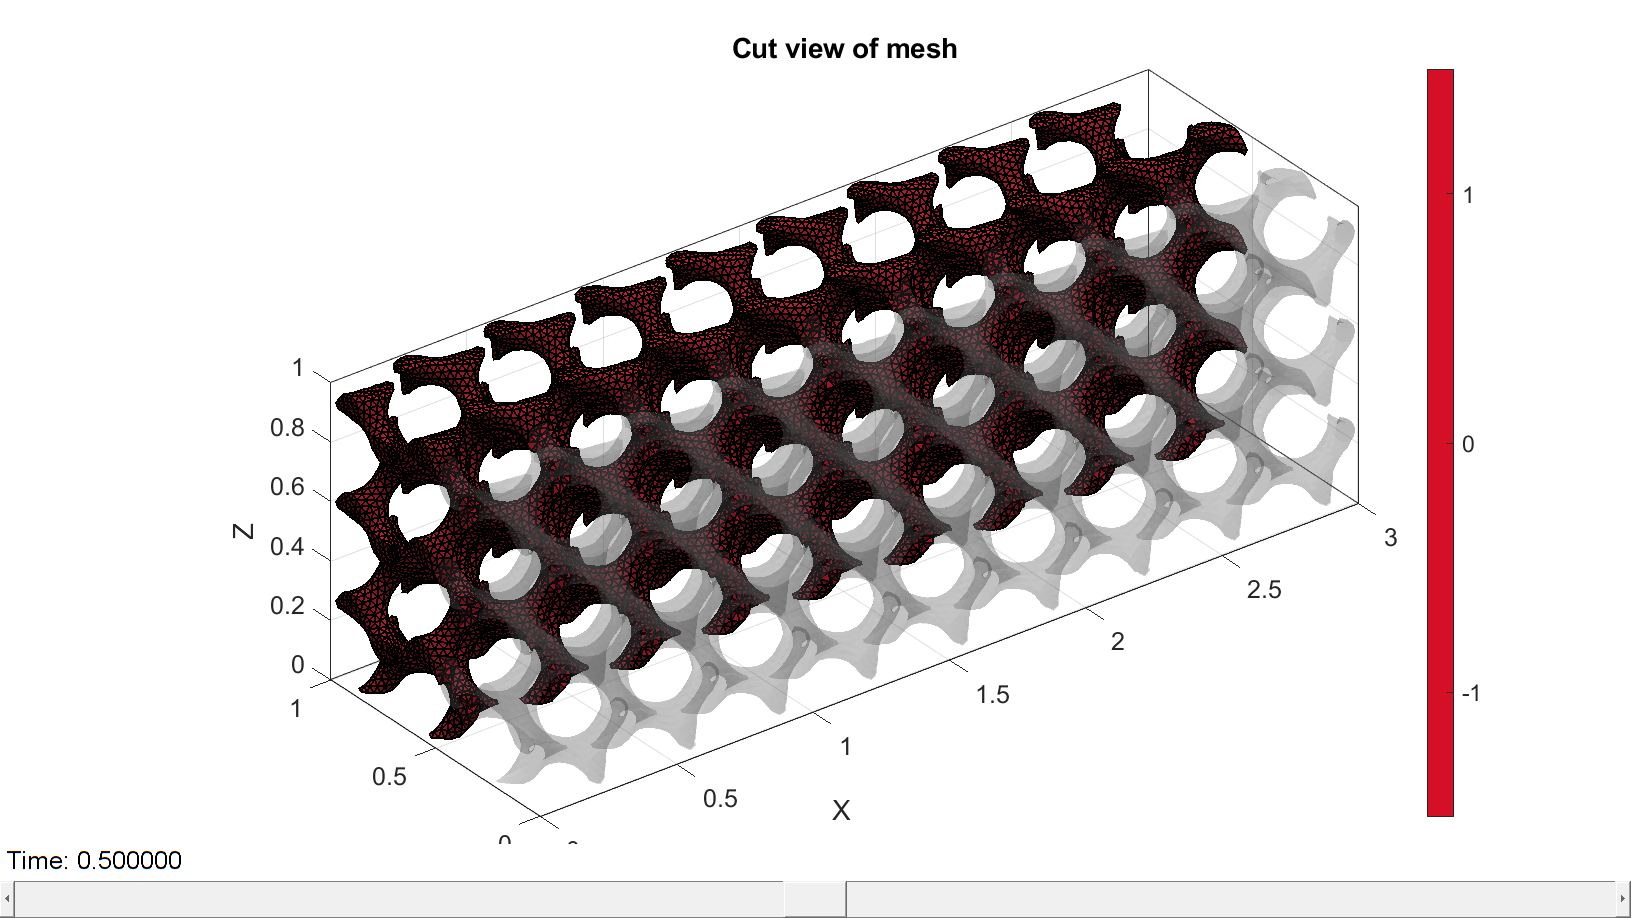

meshView(meshOutput);

## Defining node labels

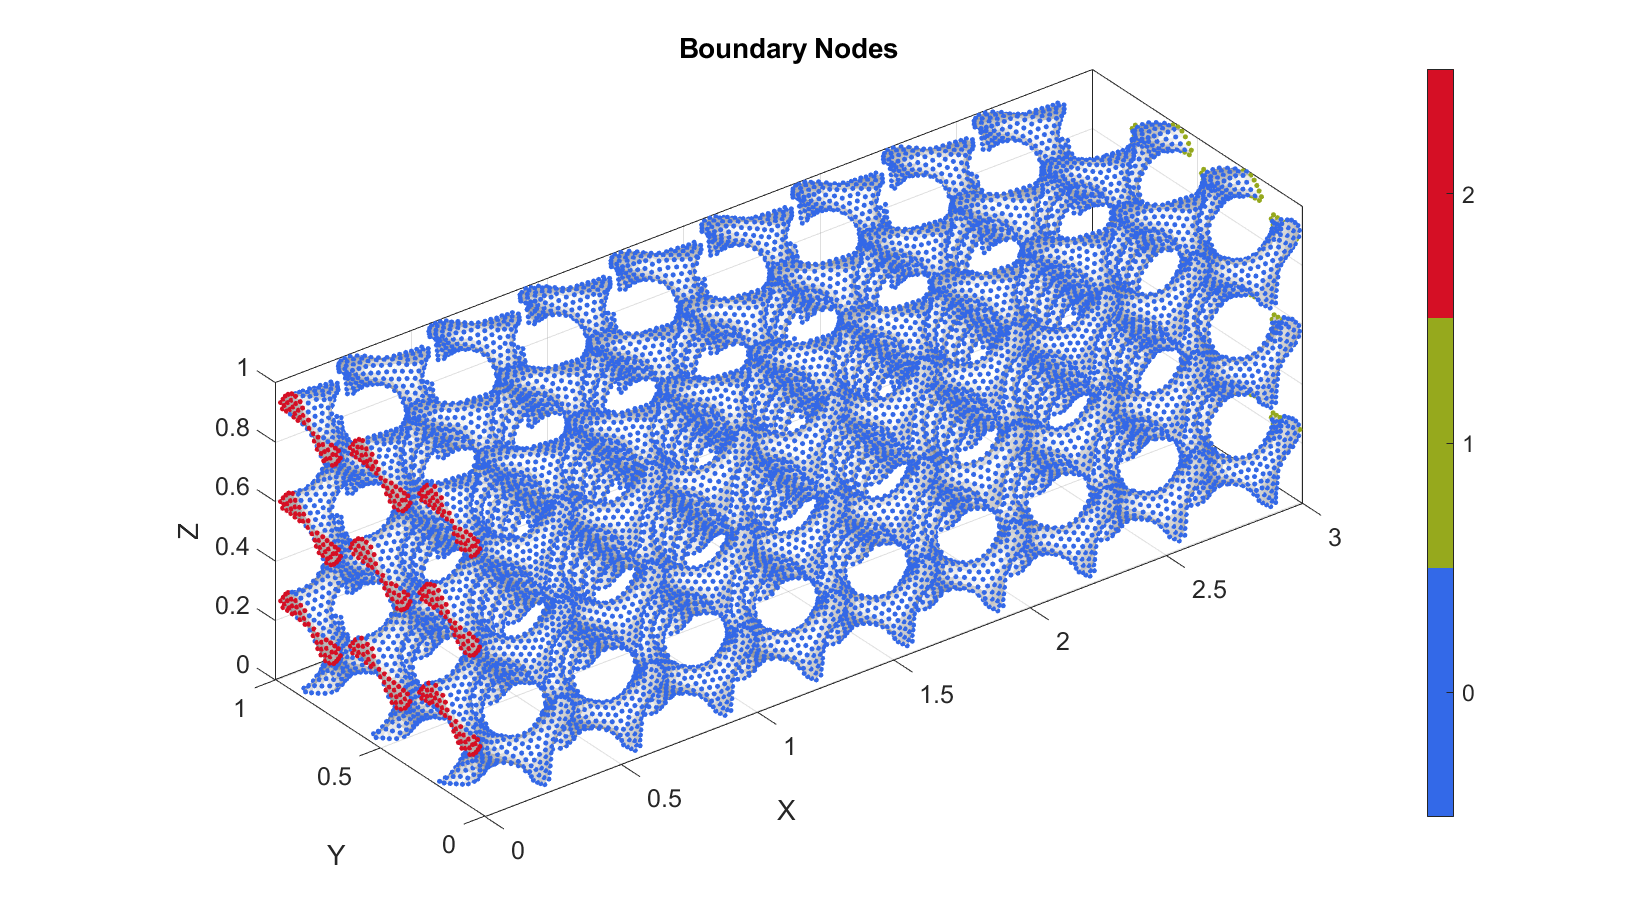

C_vertex=zeros(size(V,1),1);

% logic1=V(:,3)>(Dim(1,4)-tolDir);
logic1=V(:,1)>(3-tolDir);
logic2=V(:,1)<tolDir;

C_vertex(logic1)=max(C_vertex(:))+1;
C_vertex(logic2)=max(C_vertex(:))+1;

% Visualizing vertex/node labels
hf=cFigure;
title('Boundary Nodes','FontSize',fontSize);
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; icolorbar;
camlight headlight;

drawnow;

% red load
% yellow boundary condition

## Defining the boundary conditions

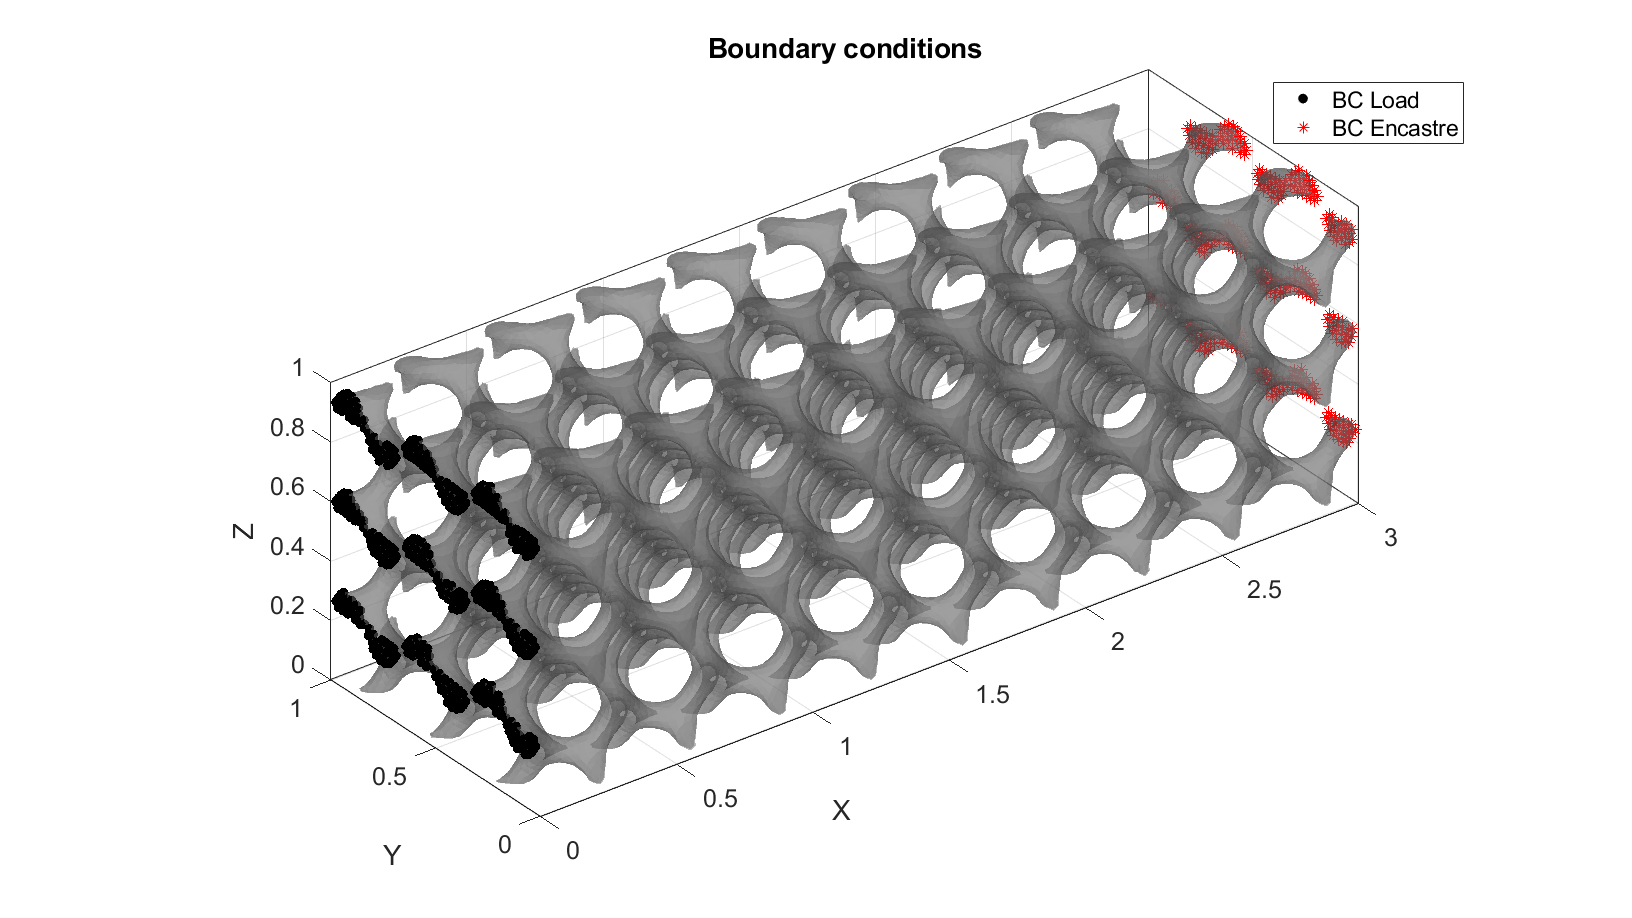

bcLoadList=find(C_vertex==2); % Load vertices
bcEncastreList=find(C_vertex==1); % Encastre vertices

% Visualizing boundary conditions. 
% Markers plotted on the semi-transparent model denote the nodes in the
% various boundary condition lists.

hl=cFigure;
title('Boundary conditions','FontSize',fontSize);
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;
gpatch(Fb,V,'kw','none',0.5);

hl(1)=plotV(V(bcLoadList,:),'k.','MarkerSize',markerSize);
hl(2)=plotV(V(bcEncastreList,:),'r*','MarkerSize',markerSize/3);
legend(hl,{'BC Load','BC Encastre'});

axisGeom(gca,fontSize);
camlight headlight;

drawnow;

## Defining the abaqus input structure

See also `abaqusStructTemplate` and `abaqusStruct2inp` and the abaqus user manual.

%%--> Heading
abaqus_spec.Heading.COMMENT{1}='Job name: ABAQUS inp file creation demo';
abaqus_spec.Heading.COMMENT{2}='Generated by: GIBBON';

%%--> Preprint
abaqus_spec.Preprint.ATTR.echo='NO';
abaqus_spec.Preprint.ATTR.model='NO';
abaqus_spec.Preprint.ATTR.history='NO';
abaqus_spec.Preprint.ATTR.contact='NO';
abaqus_spec.Preprint.ATTR.contact='NO';

%--> Part

% Node
nodeIds=(1:1:size(V,1))';
abaqus_spec.Part.COMMENT='This section defines the part geometry in terms of nodes and elements';
abaqus_spec.Part.ATTR.name='Lattice';
abaqus_spec.Part.Node={nodeIds,V};

% Element
elementIds=(1:1:size(E,1));
abaqus_spec.Part.Element{1}.ATTR.type='C3D4';%'C3D8R';
abaqus_spec.Part.Element{1}.VAL={elementIds(:),E};

% Element sets
abaqus_spec.Part.Elset{1}.ATTR.elset='Set-1';
abaqus_spec.Part.Elset{1}.VAL=elementIds;

% Sections
abaqus_spec.Part.Solid_section.ATTR.elset='Set-1';
abaqus_spec.Part.Solid_section.ATTR.material='Elastic';

%%--> Assembly
abaqus_spec.Assembly.ATTR.name='Assembly-1';
abaqus_spec.Assembly.Instance.ATTR.name='Lattice-assembly';
abaqus_spec.Assembly.Instance.ATTR.part='Lattice';

abaqus_spec.Assembly.Nset{1}.ATTR.nset='Set-1';
abaqus_spec.Assembly.Nset{1}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{1}.VAL=bcEncastreList(:)';

abaqus_spec.Assembly.Nset{2}.ATTR.nset='Set-2';
abaqus_spec.Assembly.Nset{2}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{2}.VAL=bcLoadList(:)';

abaqus_spec.Assembly.Nset{3}.ATTR.nset='all';
abaqus_spec.Assembly.Nset{3}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{3}.VAL=1:1:size(V,1);

%%--> Material
abaqus_spec.Material.ATTR.name='Elastic';
abaqus_spec.Material.Elastic=[E_youngs v_poisson];

%%--> Step
abaqus_spec.Step.ATTR.name='Step-1';
abaqus_spec.Step.ATTR.nlgeom='YES';
abaqus_spec.Step.Static=[0.01 1 1e-5 0.1];

%--> Boundary
abaqus_spec.Step.Boundary{1}.VAL={'Set-1', 'ENCASTRE'};
abaqus_spec.Step.Boundary{2}.VAL={'Set-2',[1,1],displacementMagnitude};

%--> Output
%Nodal coordinates
abaqus_spec.Step.Node_print{1}.ATTR.nset='all';
abaqus_spec.Step.Node_print{1}.ATTR.frequency = 1;
abaqus_spec.Step.Node_print{1}.VAL='COORD';

abaqus_spec.Step.El_print{1}.VAL='S';
abaqus_spec.Step.El_print{2}.VAL='E';

## writing INP file

abaqusStruct2inp(abaqus_spec,abaqusInpFileName);

## Run the job using Abaqus

lockFileName=fullfile(savePath,[abaqusInpFileNamePart,'.lck']);
if exist(lockFileName,'file')
    warning('Lockfile found and deleted')
    delete(lockFileName);
end

oldPath=pwd; %Get current working directory
cd(savePath); %Set new working directory to match save patch

abaqusPath='C:\SIMULIA\Commands\abaqus.bat';%'/usr/bin/abaqus'; %Abaqus excute command or path
[runFlag, cmdOut] = system([abaqusPath,' inp=',abaqusInpFileName,' job=',abaqusInpFileNamePart,' interactive ask_delete=OFF', 'cpus=',int2str(6)]);
disp(cmdOut);

Analysis initiated from SIMULIA established products
Abaqus JOB Lattice_FEA
Abaqus 2024
Abaqus License Manager checked out the following licenses:
Abaqus/Standard checked out 5 tokens from Flexnet server AbaqusLicense.soe.warwick.ac.uk.
<1115 out of 1120 licenses remain available>.
Begin Analysis Input File Processor
2/8/2025 12:48:29 AM
Run pre.exe
2/8/2025 12:48:37 AM
End Analysis Input File Processor
Begin Abaqus/Standard Analysis
2/8/2025 12:48:37 AM
Run standard.exe
2/8/2025 12:52:28 AM
End Abaqus/Standard Analysis
Begin SIM Wrap-up
2/8/2025 12:52:30 AM
Run SMASimUtility.exe
2/8/2025 12:52:31 AM
End SIM Wrap-up
Abaqus JOB Lattice_FEA COMPLETED




cd(oldPath); %Restore working directory

## Import and visualize abaqus results

Importing the abaqus .dat file 

% [abaqusData]=importAbaqusDat(abaqusDATFileName);

try
    % Attempt to import the Abaqus data file.
    abaqusData = importAbaqusDat(abaqusDATFileName);
catch ME
    % If import fails, open the file for reading.
    fid = fopen(abaqusDATFileName, 'rt');
    if fid == -1
        error('Unable to open file: %s', abaqusDATFileName);
    else
        fileText = fread(fid, '*char')';
        fclose(fid);

        % Check if the error message appears in the file.
        if contains(fileText, '***ERROR: Academic Teaching license is limited to 250000 nodes.')
            warning('The file %s indicates an Academic Teaching license limitation.', abaqusDATFileName);

        else % unkown error, open and manually check
            winopen(abaqusDATFileName);
        end
    end
end

% Stop the Data Collector Set
system('logman stop CPU_Log');

catch ME
    system('logman stop CPU_Log');
    rethrow(ME);
end